Change the temperature here according to your heart's desire

% open the googP_logits.mat file from get_logits folder

introduce_functions;
temperature = 100;


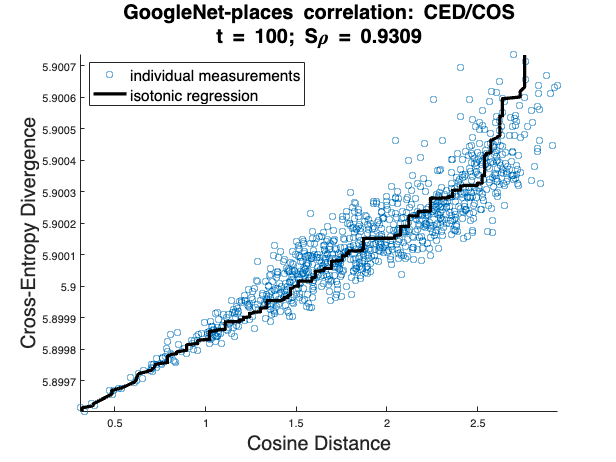


% 1 to many

googPlaces_logits = googP_logits(1:1000,:);
googPlaces_Y_logit = googP_logits(10000,:);

% so we can do the Cosine distance over the normed data - same as Euc over
% L2
googPlaces_logits_normed = googPlaces_logits ./ vecnorm(googPlaces_logits,2,2);
googPlaces_Y_logit_normed = googPlaces_Y_logit ./ norm(googPlaces_Y_logit);

smData = soft_max(googPlaces_logits,temperature);
smYData = soft_max(googPlaces_Y_logit,temperature);

dists1 = CED(smYData,smData);
dists2 = EUC(googPlaces_Y_logit_normed,googPlaces_logits_normed);


chart_title1 = strcat("GoogleNet-places"," correlation: CED/COS");
chart_title2 = strcat("t = ",num2str(temperature));
chart_title = [chart_title1,chart_title2];

shepard_spear(dists1,dists2,chart_title,"Cosine Distance","Cross-Entropy Divergence");

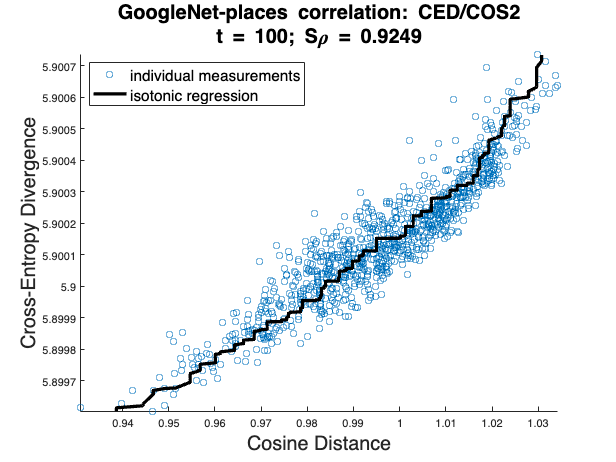

dists2 = COS(googPlaces_Y_logit,googPlaces_logits);

chart_title1 = strcat("GoogleNet-places"," correlation: CED/COS2");
chart_title2 = strcat("t = ",num2str(temperature));
chart_title = [chart_title1,chart_title2];

shepard_spear(dists1,dists2,chart_title,"Cosine Distance","Cross-Entropy Divergence");